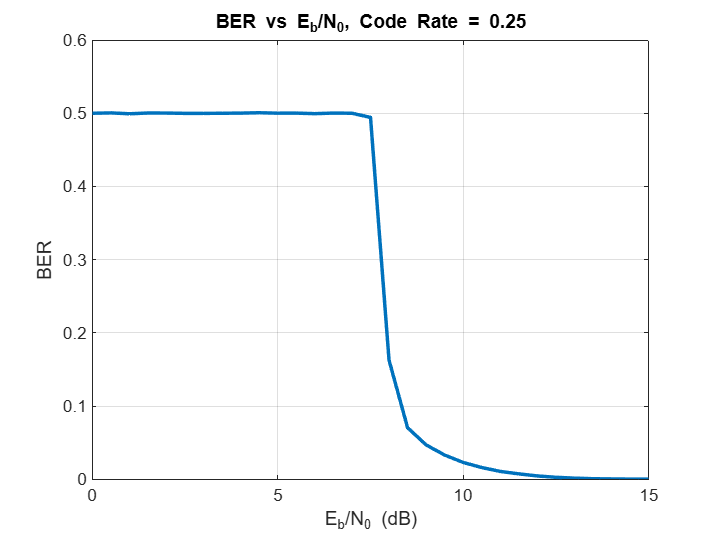

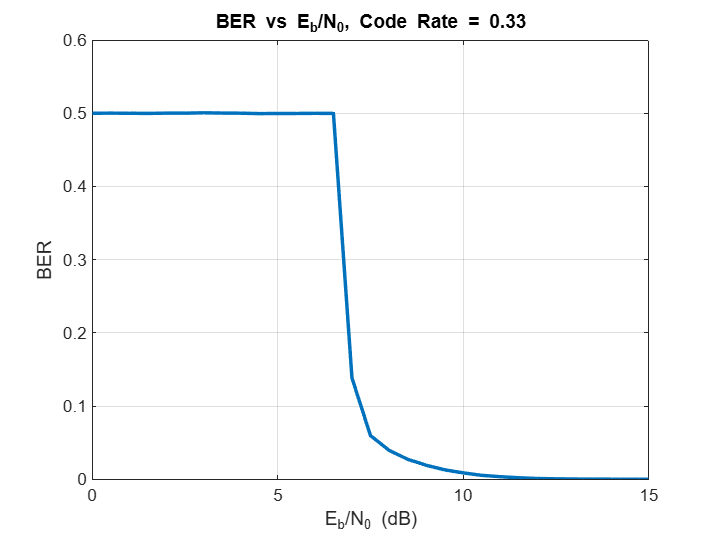

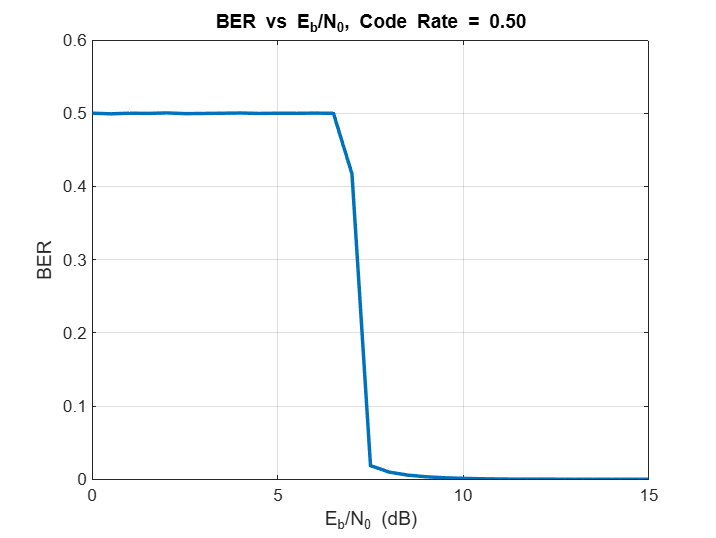

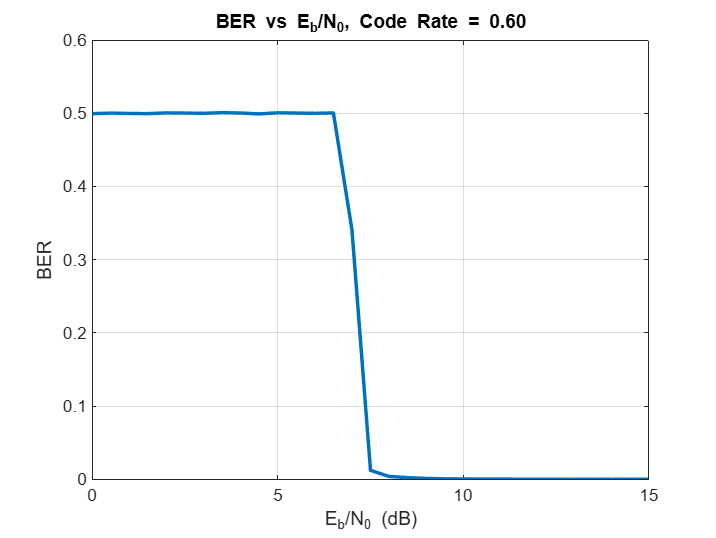

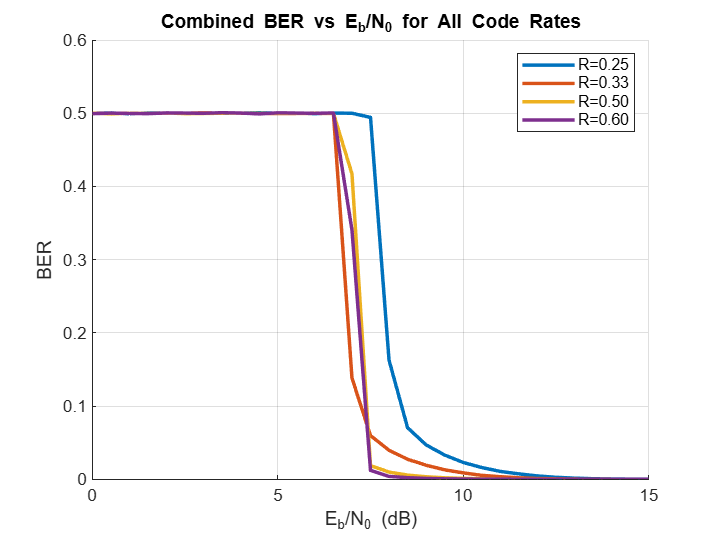

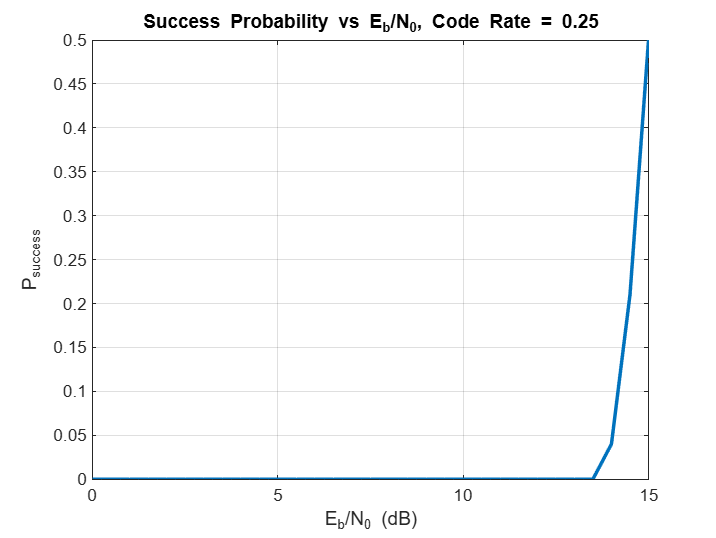

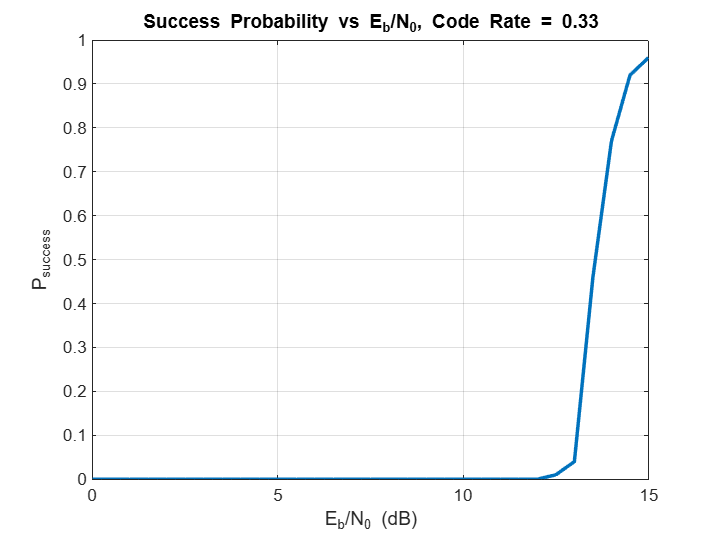

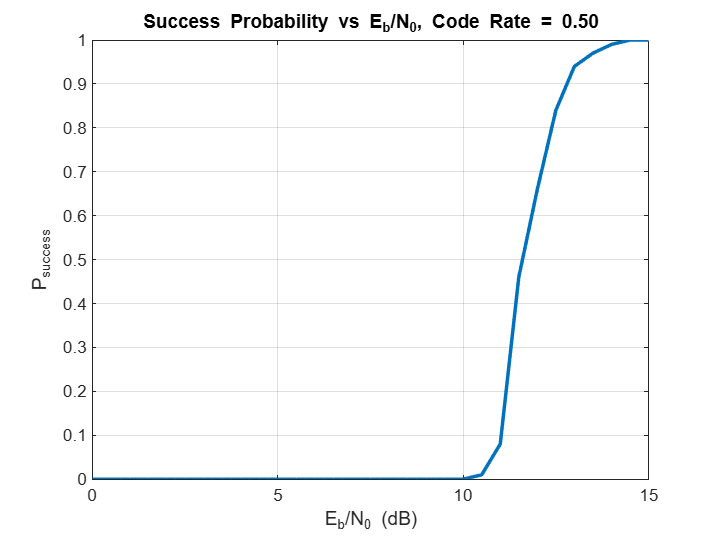

clear;
clc;

baseGraph = 'NR_2_6_52';
codeRates = [1/4, 1/3, 1/2, 3/5];
EbN0dBList = 0 : 0.5 : 30;
numTrials = 100;
maxIterations = 20;

[B, Hfull, z] = nrldpc_Hmatrix(baseGraph);
[mb, nb] = size(B);
kb = nb - mb;
numInfoBits = kb * z;
parityCols = kb - 2;

decodingErr = zeros(length(codeRates), numel(EbN0dBList));
probSuccess = zeros(length(codeRates), numel(EbN0dBList));

for rIdx = 1 : length(codeRates)
    rate = codeRates(rIdx);
    [H, blockLen] = H_matrix(Hfull, z, mb, nb, parityCols, rate);
    c2v_map = get_c2v(H);
    v2c_map = get_v2c(H);

    for eIdx = 1 : length(EbN0dBList)
        EbN0dB = EbN0dBList(eIdx);

        for trial = 1:numTrials
            
            msg = randi([0, 1], numInfoBits, 1);
            codeword = encodeLDPC(B, z, msg, blockLen);

            tx = 1 - 2 * codeword;
            rx = addAWGN(tx, rate, EbN0dB);

            [decBits, success] = hardDecoding(H, rx, maxIterations, c2v_map, v2c_map);

            decodingErr(rIdx, eIdx) = decodingErr(rIdx, eIdx) + bitErrorRate(codeword, decBits);
            probSuccess(rIdx, eIdx) = probSuccess(rIdx, eIdx) + success;
        end

        decodingErr(rIdx, eIdx) = decodingErr(rIdx, eIdx) / numTrials;
        probSuccess(rIdx, eIdx) = probSuccess(rIdx, eIdx) / numTrials;
    end
end

plotIndividualAndCombined(EbN0dBList, decodingErr, probSuccess, codeRates);

          


function plotIndividualAndCombined(EbN0dBList, decodingErr, probSuccess, codeRates)
    
    for i = 1:numel(codeRates)
        figure;
        plot(EbN0dBList, decodingErr(i, :), 'LineWidth', 2);
        grid on;
        xlabel('E_b/N_0 (dB)');
        ylabel('BER');
        title(sprintf('BER vs E_b/N_0, Code Rate = %.2f', codeRates(i)));
    end

    figure;
    hold on;
    for i = 1:numel(codeRates)
        plot(EbN0dBList, decodingErr(i, :), 'LineWidth', 2);
    end

    grid on;
    xlabel('E_b/N_0 (dB)');
    ylabel('BER');
    title('Combined BER vs E_b/N_0 for All Code Rates');
    legend(arrayfun(@(r) sprintf('R=%.2f', r), codeRates, 'UniformOutput', false));

    for i = 1 : length(codeRates)
        figure;
        plot(EbN0dBList, probSuccess(i, :), 'LineWidth', 2);
        grid on;
        xlabel('E_b/N_0 (dB)');
        ylabel('P_{success}');
        title(sprintf('Success Probability vs E_b/N_0, Code Rate = %.2f', codeRates(i)));
    end

    figure;
    hold on;
    for i = 1:numel(codeRates)
        plot(EbN0dBList, probSuccess(i, :), 'LineWidth', 2);
    end

    grid on;
    xlabel('E_b/N_0 (dB)');
    ylabel('P_{success}');
    title('Combined Success Probability vs E_b/N_0 for All Code Rates');
    legend(arrayfun(@(r) sprintf('R=%.2f', r), codeRates, 'UniformOutput', false));
end

function [H, nBlockLength] = H_matrix(Hfull, z, mb, nb, parityCols, rate)
    nbRM = min(ceil(parityCols / rate) + 2, nb); 
    nBlockLength = nbRM * z;
    Htrunc = Hfull(:, 1:nBlockLength);
    nChecksRemain = mb * z - nb * z + nBlockLength;
    H = Htrunc(1:nChecksRemain, :);
end

function c = encodeLDPC(B, z, msg, nBlockLength)
    cw = nrldpc_encode(B, z, msg');
    c = cw(1:nBlockLength)';
end

function rx = addAWGN(tx, rate, EbN0dB)
    gamma = 10^(EbN0dB / 10);
    sigma = sqrt(1 / (2 * rate * gamma));
    rx = tx + sigma * randn(size(tx));
end

function [decodedBits, success] = hardDecoding(H, rx, maxIter, c2v_map, v2c_map)
    nVars   = size(H, 2);
    decoded = (rx < 0);
    prev    = decoded;
    success = false;

    % Initialize VN->CN messages
    v2c_msgs = zeros(size(H));
    for vn = 1:nVars
        for cn = v2c_map{vn}
            v2c_msgs(cn, vn) = decoded(vn);
        end
    end
    c2v_msgs = zeros(size(H));

    for iter = 1:maxIter
        % Check->Variable update
        for cn = 1:numel(c2v_map)
            vn_list = c2v_map{cn};
            xor_val = 0;
            for vn = vn_list
                xor_val = xor(xor_val, v2c_msgs(cn, vn));
            end
            for vn = vn_list
                c2v_msgs(cn, vn) = xor(xor_val, v2c_msgs(cn, vn));
            end
        end

        % Variable->Check update and new estimate
        new_est = zeros(nVars, 1);
        for vn = 1:nVars
            cn_list  = v2c_map{vn};
            dv       = numel(cn_list);
            totalOnes = decoded(vn) + sum(c2v_msgs(cn_list, vn));

            for cn = cn_list
                excl = totalOnes - c2v_msgs(cn, vn);
                v2c_msgs(cn, vn) = (excl > dv/2);
            end

            new_est(vn) = (totalOnes > floor(dv/2));
        end

        % Syndrome check
        if all(mod(H * new_est, 2) == 0)
            decoded = new_est;
            success = true;
            break;
        end
        if isequal(new_est, prev)
            decoded = new_est;
            break;
        end

        prev    = new_est;
        decoded = new_est;
    end

    decodedBits = decoded;
end

function c2v = get_c2v(H)
    for i = 1:size(H,1)
        c2v{i} = find(H(i,:));
    end
end

function v2c = get_v2c(H)
    for j = 1:size(H,2)
        v2c{j} = find(H(:,j))';
    end
end

function ber = bitErrorRate(orig, dec)
    ber = sum(xor(orig, dec)) / numel(orig);
end

function [B, H, z] = nrldpc_Hmatrix(BG)
    load(sprintf('%s.txt', BG), BG);
    B = eval(BG);
    [mb, nb] = size(B);
    z        = max(B(:)) + 1;
    Iz       = eye(z);
    I0       = zeros(z);
    H        = zeros(mb*z, nb*z);

    for ii = 1:mb
        rows = (ii-1)*z + (1:z);
        for jj = 1:nb
            cols = (jj-1)*z + (1:z);
            if B(ii,jj) == -1
                H(rows, cols) = I0;
            else
                H(rows, cols) = circshift(Iz, -B(ii,jj));
            end
        end
    end
end

function cword = nrldpc_encode(B, z, msg)
    [m, n] = size(B);
    cword  = zeros(1, n*z);
    cword(1:(n-m)*z) = msg;
    temp   = zeros(1, z);

    for i = 1:4
        for j = 1:(n-m)
            temp = mod(temp + mul_sh(msg((j-1)*z+1:j*z), B(i,j)), 2);
        end
    end

    if B(2, n-m+1) == -1
        p = B(3, n-m+1);
    else
        p = B(2, n-m+1);
    end
    cword((n-m)*z+1:(n-m+1)*z) = mul_sh(temp, z-p);

    for i = 1:3
        temp = zeros(1, z);
        for j = 1:(n-m+i)
            temp = mod(temp + mul_sh(cword((j-1)*z+1:j*z), B(i,j)), 2);
        end
        cword((n-m+i)*z+1:(n-m+i+1)*z) = temp;
    end

    for i = 5:m
        temp = zeros(1, z);
        for j = 1:(n-m+4)
            temp = mod(temp + mul_sh(cword((j-1)*z+1:j*z), B(i,j)), 2);
        end
        cword((n-m+i-1)*z+1:(n-m+i)*z) = temp;
    end
end

function y = mul_sh(x, k)
    if k == -1
        y = zeros(1, length(x));
    else
        y = [x(k+1:end), x(1:k)];
    end
end

